Function

f=@(x) 400.*x.^5 - 900.*x.^4 + 675.*x.^3 - 200.*x.^2 + 25.*x + 0.2;

xx = linspace(0, 0.8);
yy = f(xx)

yy =     0.2000    0.3893    0.5546    0.6978    0.8209    0.9258    1.0140    1.0874    1.1474    1.1956    1.2334    1.2621    1.2829    1.2972    1.3059    1.3101    1.3108    1.3090    1.3054    1.3008    1.2960    1.2915    1.2881    1.2862    1.2863    1.2889    1.2943    1.3029    1.3148    1.3305    1.3500    1.3735    1.4010    1.4327    1.4686    1.5086    1.5527    1.6007    1.6527    1.7083    1.7675    1.8300    1.8956    1.9640    2.0349    2.1081    2.1832    2.2598    2.3377    2.4164


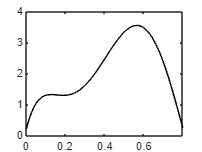

plot(xx,yy,'k-')
axis([0 0.8 0 4])

To integrate function from 0 to 0.8

a = 0;
b = 0.8;

p = [400 -900 675 -200 25 0.2]

p =   400.0000 -900.0000  675.0000 -200.0000   25.0000    0.2000


q = polyint(p)

q =    66.6667 -180.0000  168.7500  -66.6667   12.5000    0.2000         0



Itrue = diff(polyval(q, [a b]))

Itrue = 1.6405

Plot original function along with trapezoidal rule ns = 1

ns = 1;

x = linspace(0, 0.8, ns+1)

x =          0    0.8000


y = f(x)

y =     0.2000    0.2320


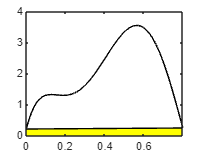



area(x,y,'FaceColor','y','EdgeColor','black','LineStyle','-')
hold on
plot(xx,yy,'k-')
hold off
axis([0 0.8 0 4])



p = polyfit(x,y,1);
q = polyint(p);
I1 = diff(polyval(q, [a b]))

I1 = 0.1728

Plot original function along with trapezoidal rule ns = 2

ns = 2;

x = linspace(0, 0.8, ns+1)

x =          0    0.4000    0.8000


y = f(x)

y =     0.2000    2.4560    0.2320



figure
color = ['g','y']

color = 'gy'

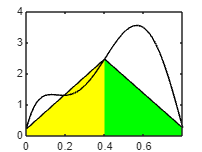

for i = 1:ns
    area(x(i:i+1),y(i:i+1),'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')
    hold on
end

plot(xx,yy,'k-')
hold off
axis([0 0.8 0 4])



I2 = trap(f,a,b,2)

I2 = 1.0688

% q = polyint(x)
% Itrue2 = diff(polyval(q, [a b]))
et = (Itrue - I2)/Itrue*100

et = 34.8505

Plot original function along with trapezoidal rule ns = 3

ns = 3;

x = linspace(0, 0.8, ns+1)

x =          0    0.2667    0.5333    0.8000


y = f(x)

y =     0.2000    1.4327    3.4872    0.2320



figure
color = ['g','y']

color = 'gy'

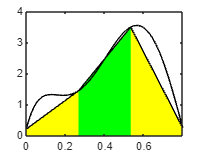

for i = 1:ns
    area(x(i:i+1),y(i:i+1),'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')
    hold on
end

plot(xx,yy,'k-')
hold off
axis([0 0.8 0 4])

Plot original function along with trapezoidal rule ns from 1 until 10

ns = 30;

x = linspace(0, 0.8, ns+1)

x =          0    0.0267    0.0533    0.0800    0.1067    0.1333    0.1600    0.1867    0.2133    0.2400    0.2667    0.2933    0.3200    0.3467    0.3733    0.4000    0.4267    0.4533    0.4800    0.5067    0.5333    0.5600    0.5867    0.6133    0.6400    0.6667    0.6933    0.7200    0.7467    0.7733    0.8000


y = f(x)

y =     0.2000    0.7368    1.0597    1.2300    1.2993    1.3102    1.2969    1.2861    1.2973    1.3437    1.4327    1.5667    1.7434    1.9570    2.1984    2.4560    2.7163    2.9648    3.1860    3.3650    3.4872    3.5396    3.5112    3.3937    3.1819    2.8749    2.4761    1.9944    1.4444    0.8475    0.2320



figure
color = ['g','y']

color = 'gy'

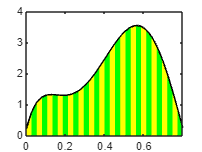

for i = 1:ns
    area(x(i:i+1),y(i:i+1),'FaceColor',color(mod(i,2)+1),'EdgeColor','black','LineStyle','-')
    hold on
end

plot(xx,yy,'k-')
hold off
axis([0 0.8 0 4])

for ea < 0.1